## Spectrogram Generation 

### Control Signals

% Locate the TVALID and TLAST control signals of the FFT
fft_out_tvalid = out.TVALID

fft_out_tvalid =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


find(fft_out_tvalid == 1, 1)

ans = 4237

fft_out_tlast = out.TLAST

fft_out_tlast =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


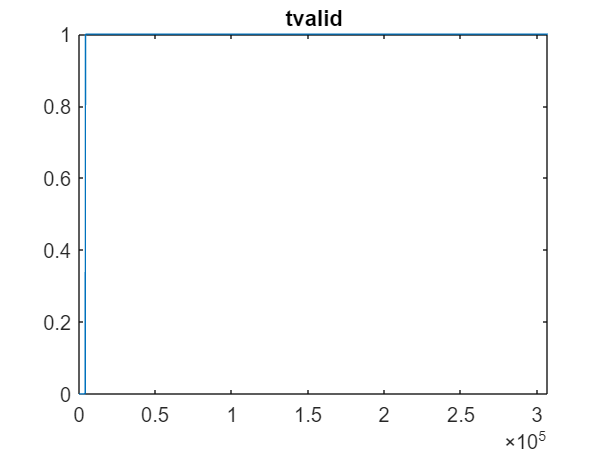

plot(1:length(fft_out_tvalid),fft_out_tvalid)
title('tvalid')

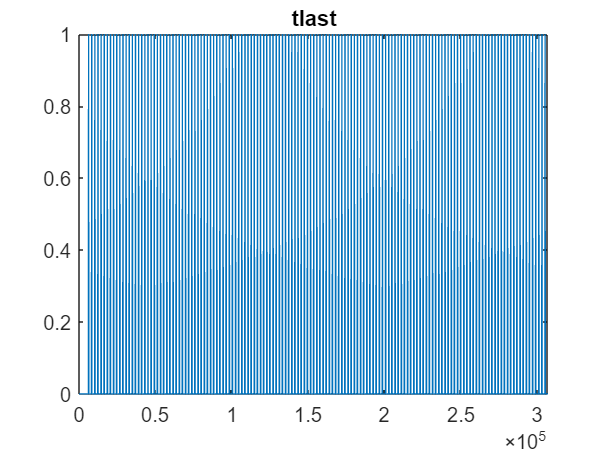

plot(1:length(fft_out_tlast),fft_out_tlast)
title('tlast')

### HDL block floating point 

% Locate the FFT data output
fft_out_log_ = out.FFT_out_log

fft_out_log_ =      0
     0
     0
     0
  -512
  -512
  -512
  -512
  -512
  -512


% Only keep the valid samples
fft_out_log = fft_out_log_(find(fft_out_tvalid == 1, 1):end)

fft_out_log =  -130.9604
 -130.9604
 -129.7863
 -129.7863
 -129.7863
 -129.7863
 -129.7863
 -129.7863
 -129.7863
 -128.8861


% Zero-pad if neccessary to ensure # samples is an integer multiple of the
% window size (required for easier spectrogram plotting)
fft_length_before_zero_padding = (ceil(length(fft_out_log)/N))

fft_length_before_zero_padding = 148


% Set the zero-padded values to the minimum value of the valid samples
fft_out_log(length(fft_out_log)+1:fft_length_before_zero_padding*N)=min(fft_out_log)

fft_out_log =  -130.9604
 -130.9604
 -129.7863
 -129.7863
 -129.7863
 -129.7863
 -129.7863
 -129.7863
 -129.7863
 -128.8861



% Determine key parameters
Total_Num_Samples = length(fft_out_log)

Total_Num_Samples = 303104

Num_Segments = Total_Num_Samples/N

Num_Segments = 148


% Create the frequency and time axis for both spectrograms
f_axis_1N = (n/N*fs)/1e6; % From 0 -> fs
f_axis_1N_ = (-N/2:N/2-1)*(fs/N)/1e6; % From -fs/2 -> fs/2 (combined with fftshift for centring DC - as high f is just a spectral replication of -ve f)
t_axis_1N = linspace(0,Total_Num_Samples/fs,Num_Segments)

t_axis_1N =          0    0.0001    0.0003    0.0004    0.0005    0.0006    0.0008    0.0009    0.0010    0.0012    0.0013    0.0014    0.0015    0.0017    0.0018    0.0019    0.0021    0.0022    0.0023    0.0024    0.0026    0.0027    0.0028    0.0030    0.0031    0.0032    0.0034    0.0035    0.0036    0.0037    0.0039    0.0040    0.0041    0.0043    0.0044    0.0045    0.0046    0.0048    0.0049    0.0050    0.0052    0.0053    0.0054    0.0055    0.0057    0.0058    0.0059    0.0061    0.0062    0.0063


t_axis_1N = 1e3.*t_axis_1N

t_axis_1N =          0    0.1289    0.2577    0.3866    0.5155    0.6444    0.7732    0.9021    1.0310    1.1598    1.2887    1.4176    1.5464    1.6753    1.8042    1.9331    2.0619    2.1908    2.3197    2.4485    2.5774    2.7063    2.8352    2.9640    3.0929    3.2218    3.3506    3.4795    3.6084    3.7373    3.8661    3.9950    4.1239    4.2527    4.3816    4.5105    4.6393    4.7682    4.8971    5.0260    5.1548    5.2837    5.4126    5.5414    5.6703    5.7992    5.9281    6.0569    6.1858    6.3147


f_axis = repmat(f_axis_1N,1,Num_Segments)

f_axis =          0    0.0078    0.0156    0.0234    0.0312    0.0391    0.0469    0.0547    0.0625    0.0703    0.0781    0.0859    0.0938    0.1016    0.1094    0.1172    0.1250    0.1328    0.1406    0.1484    0.1562    0.1641    0.1719    0.1797    0.1875    0.1953    0.2031    0.2109    0.2188    0.2266    0.2344    0.2422    0.2500    0.2578    0.2656    0.2734    0.2812    0.2891    0.2969    0.3047    0.3125    0.3203    0.3281    0.3359    0.3438    0.3516    0.3594    0.3672    0.3750    0.3828


f_axis_ = repmat(f_axis_1N_,1,Num_Segments)

f_axis_ =    -8.0000   -7.9922   -7.9844   -7.9766   -7.9688   -7.9609   -7.9531   -7.9453   -7.9375   -7.9297   -7.9219   -7.9141   -7.9062   -7.8984   -7.8906   -7.8828   -7.8750   -7.8672   -7.8594   -7.8516   -7.8438   -7.8359   -7.8281   -7.8203   -7.8125   -7.8047   -7.7969   -7.7891   -7.7812   -7.7734   -7.7656   -7.7578   -7.7500   -7.7422   -7.7344   -7.7266   -7.7188   -7.7109   -7.7031   -7.6953   -7.6875   -7.6797   -7.6719   -7.6641   -7.6562   -7.6484   -7.6406   -7.6328   -7.6250   -7.6172


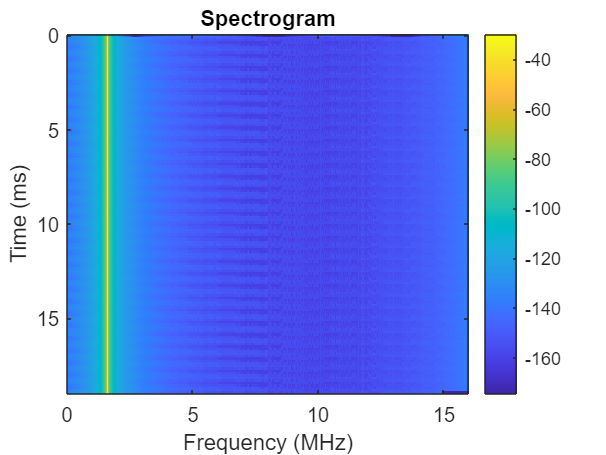


% Fill in the arrays to plot the spectrograms
for i=1:Num_Segments
    index = (i-1)*N+1 : i*N;
    t_axis(index) = t_axis_1N(i);
    Data(i,:) = fft_out_log(index);
    Data_shift(i,:) = fftshift(Data(i,:));
end

% Plot spectrograms 
figure;
imagesc(f_axis,t_axis,Data)
title('Spectrogram')
xlabel('Frequency (MHz)')
ylabel('Time (ms)')
colorbar

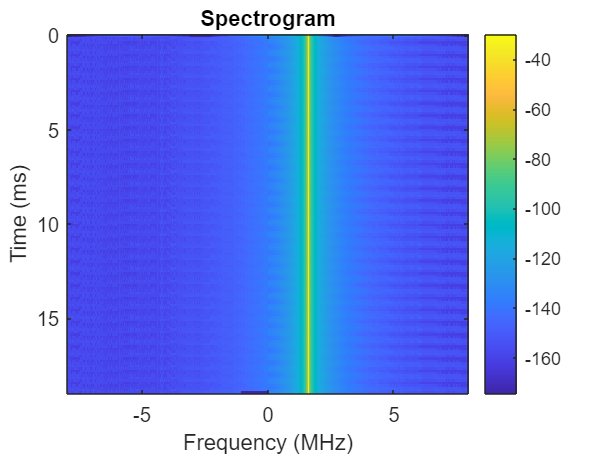

figure;
imagesc(f_axis_,t_axis,Data_shift)
title('Spectrogram')
xlabel('Frequency (MHz)')
ylabel('Time (ms)')
colorbar

Data_log_hdl = reshape(Data,[1,numel(Data)])

Data_log_hdl =  -130.9604 -135.3215 -132.0552 -134.7728 -139.9494 -142.3416 -135.3215 -132.0552 -134.7728 -139.9494 -142.3416 -135.3215 -132.0552 -134.7728 -139.9494 -142.3416 -135.3215 -132.0552 -134.7728 -139.9494 -142.3416 -135.3215 -132.0552 -134.7728 -139.9494 -142.3416 -135.3215 -132.0552 -134.7728 -139.9494 -142.3416 -135.3215 -132.0552 -134.7728 -139.9494 -142.3416 -135.3215 -132.0552 -134.7728 -139.9494 -142.3416 -135.3215 -132.0552 -134.7728 -139.9494 -142.3416 -135.3215 -132.0552 -134.7728 -139.9494


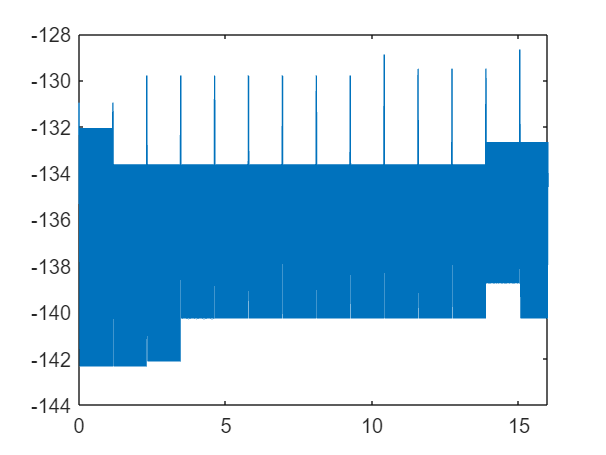

% Plot 1st spectrum
figure;
plot(f_axis(1:2048),Data_log_hdl(1:2048))